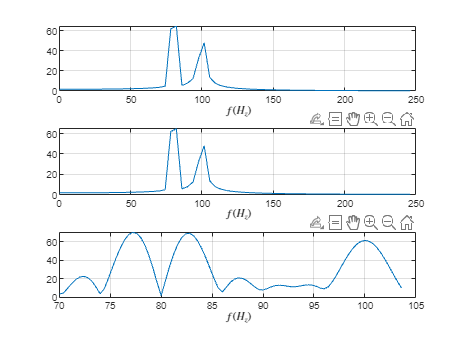

N=128;f1=78;f2=82;f3=100;fs=500;
stepf=fs/N;n=0:N-1;
t=n/fs;n1=0:stepf:fs/2-stepf;
x=sin(2*pi*f1*t)+sin(2*pi*f2*t)+sin(2*pi*f3*t);
M=N;
W=exp(-1j*2*pi/M);
A=1;
Y1=czt(x,M,W,A);
subplot(311);plot(n1,abs(Y1(1:N/2)));
xlabel('$f(H_z)$',Interpreter='latex')
grid on;
Y2=abs(fft(x));
subplot(312);plot(n1,abs(Y2(1:N/2)));
xlabel('$f(H_z)$',Interpreter='latex')
grid on;
M=85;f0=70;DELF=0.4;
A=exp(1j*2*pi*f0/fs);
W=exp(-1j*2*pi*DELF/fs);
Y3=czt(x,M,W,A);
n2=f0:DELF:f0+(M-1)*DELF;
subplot(313);plot(n2,abs(Y3));
xlabel('$f(H_z)$',Interpreter='latex')
grid on;